Miscelaneous Plots for the Assignment

out = sim("NonLinearModel.slx");

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torque =
     0

wind_torqu

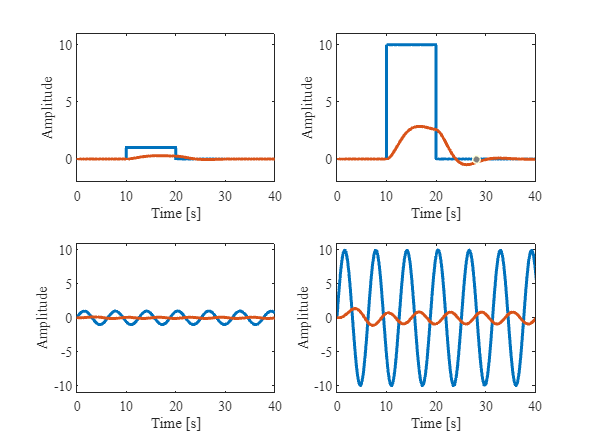


%  Step Response

y = out.condition1;
step_1 = y.signals.values(:,1);
resp_1 = y.signals.values(:,2);
step_2 = y.signals.values(:,3);
resp_2 = y.signals.values(:,4);

t = out.tout;

subplot(2,2,1)
plot(t, step_1, LineWidth=2)
hold on 
plot(t, resp_1, LineWidth=2)
ylim([-2 11])
xlim([0 40])
xlabel("Time [s]")
ylabel("Amplitude")
% legend("Step Input", "Response")
fontname("Times New Roman", 11)

subplot(2,2,2)
plot(t, step_2, LineWidth=2)
hold on
plot(t, resp_2, LineWidth=2)
ylim([-2 11])
xlim([0 40])
xlabel("Time [s]")
ylabel("Amplitude")
% legend("Step Input", "Response")
fontname("Times New Roman", 11)

% Sin Response
y = out.condition2;
step_1 = y.signals.values(:,1);
resp_1 = y.signals.values(:,2);
step_2 = y.signals.values(:,3);
resp_2 = y.signals.values(:,4);

t = out.tout;

subplot(2,2,3)
plot(t, step_1, LineWidth=2)
hold on 
plot(t, resp_1, LineWidth=2)
ylim([-11 11])
xlim([0 40])
xlabel("Time [s]")
ylabel("Amplitude")
fontname("Times New Roman", 11)

subplot(2,2,4)
plot(t, step_2, LineWidth=2)
hold on
plot(t, resp_2, LineWidth=2)
ylim([-11 11])
xlim([0 40])
xlabel("Time [s]")
ylabel("Amplitude")
fontname("Times New Roman", 11)

Manual Nyquist Plot

Adapted from Class Example CH6_Stability_examples_Nyquist_GM_PM.m 

Reference:

Dr Aarti Panday (2024). CH6_Stability_examples_Nyquist_GM_PM (https://ulwazi.wits.ac.za/courses/55030/files/7012610?module_item_id=740820), Ulwazi - MECN4029A Mechatronics. Retrieved May 17 2024

K = 1;
omega_complex = 0:0.01:10000;
real_s_ex1comp = (23.7894.*K.*(71.4275+23.7894.*K-306.7708.*omega_complex.^2))./((71.4275+23.7894.*K-306.7708.*omega_complex.^2).^2+(182.0498.*omega_complex-omega_complex.^3).^2);
imag_s_ex1comp = (-23.7894.*K.*(182.0498.*omega_complex-omega_complex.^3))./((71.4275+23.7894.*K-306.7708.*omega_complex.^2).^2+(182.0498.*omega_complex-omega_complex.^3).^2);
figure;plot(real_s_ex1comp,imag_s_ex1comp); hold on; grid; plot (-1,0,'X', 'MarkerSize',10);

real_s_ex1comp_cc = (23.7894.*K.*(71.4275+23.7894.*K-306.7708.*omega_complex.^2))./((71.4275+23.7894.*K-306.7708.*omega_complex.^2).^2+(182.0498.*omega_complex-omega_complex.^3).^2);
imag_s_ex1comp_cc = (23.7894.*K.*(182.0498.*omega_complex-omega_complex.^3))./((71.4275+23.7894.*K-306.7708.*omega_complex.^2).^2+(182.0498.*omega_complex-omega_complex.^3).^2);
hold on; plot(real_s_ex1comp_cc,imag_s_ex1comp_cc);
% axis([-1 1 -0.5 0.5]);
% title('K = 1 stable does not encircle point -1,0i');
xlabel("Real Axis")
ylabel("Imaginary Axis")
fontname("Times New Roman")